# **Aerial Robotics**

## **Week 1**

Welcome to Week 1 of the Aerial Robotics course!! 

We hope you liked the Week 0 material and are now equipped with a good understanding of MATLAB basics.

This week, you will be introduced to the exciting field of Unmanned Aerial Vehicles (UAVs) and quadrotors in particular. You will be introduced to the realms of autonomous flight and learn about the basic mechanics of quadcopters. The major learning objectives for this course are as follows:

- Basic mechanics model study for quadcopters

- Thrust Analysis and appropriate motor sizing for the UAV

- Basics of PID Control and PID Tuning

- Application of PID for 1-D(altitude) controller for a quadcopter

## **Introduction to UAVs:**

UAVs have been a great sector for innovation in the modern industry for several years. Several commercial applications have found their ways in modern UAVs be it agriculture, photography, inspection, construction, border patrols and producing movies. Among these quadcopters are clearly the most developed and common configuration used. Let’s have a general overview of the quadcopter configuration first.

[Quadrotors](https://www.youtube.com/watch?v=TW_yTFrc9rc)

For most of the commercial operations, UAVs are being designed for autonomous flight. This domain itself has several subdomains each of which has defined objectives for the UAV. Lets gather an understanding of the different key components of autonomous flight.

[Key Components of Autonomous Flight](https://www.youtube.com/watch?v=Y1twsFRqZQQ)

[State estimation](https://www.youtube.com/watch?v=ppo6dzQ7OwU)

## **Basic Mechanics:**

Now that we have understood the four subdomains of autonomous flight, we move further. In this course, as mentioned before the major focus would be towards learning and formulating control systems for the quadrotors. We will start by building an understanding towards the underlying physics of quadcopter control.

Let us first have a look at the basic mechanics modelling of the quadcopter which governs the control law and control commands. The below video will take you through the force and torque modelling with respect to the motors of the UAV and will present a methodology towards appropriate motor sizing and thereby its selection. 

[Basic Mechanics](https://www.youtube.com/watch?v=ZEN4X185Z8M)

The basic strategy while sizing the motors for our quadcopter is as follows:

- We get the propeller specifications and get its force coefficient $k_F$ and the moment coefficient $k_M$. These coefficients allow us to co-relate the thrust generated by the propeller at a particular angular velocity as well as the drag moment which the propellers encounter at that angular velocity

                                            $F=k_F\omega^2$;  $M_D=k_M\omega^2$

         2.  Then, the motors specifications are utilised to obtain a torque-angular velocity relation called motor profile.

         3.For a quadcopter to hover, the thrust provided by every propeller must equalise $\frac{mg}{4}$. The propeller force curve is checked for the optimum angular velocity for providing this thrust.

         4. Using this angular velocity, drag moment experienced by the propellers is calculated 

         5. The drag moment has to be countered by the motor torque, so the the motor has to be selected in a way that at the obtained optimum angular velocity, it should be able to provide sufficient torque to overcome the drag moment.

Here is an example exercise for you to understand and solve motor sizing problems.

Example: Given $F_i = k_F (\omega_i/1000)^2$ where $k_F = 1
$N/rpmsq, and $D_i = k_M (\omega_i/1000) ^2$ where $k_M = 2$Nm/rpmsq, weight = $mg = 40 N$, now we have three motors whose force to angular velocity characteristics are as follows: $\tau_1 = \frac{10\sqrt{10}}{\omega};
\tau_2 = \frac{20\sqrt{10}}{\omega};
\tau_3 = \frac{30\sqrt{10}}{\omega}
$. which motor is suitable for use?

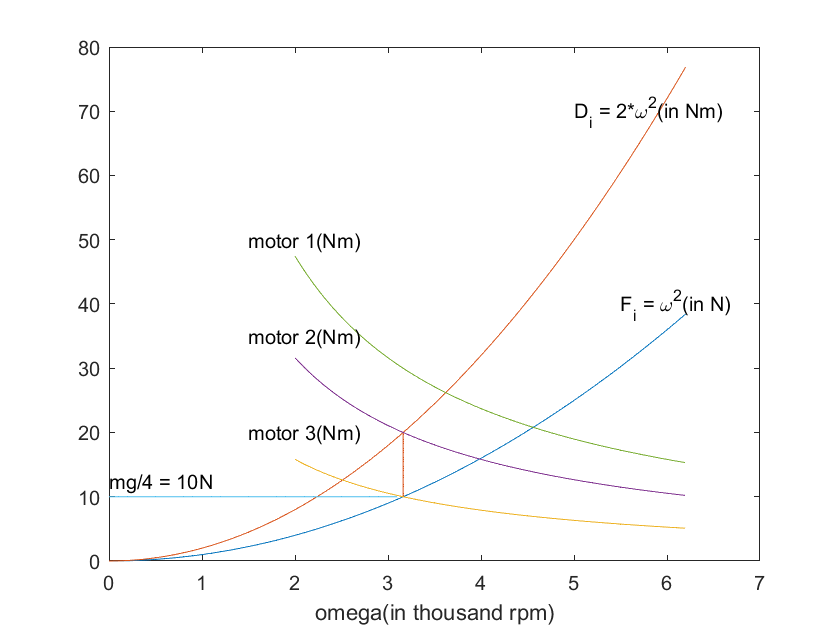

omega = 0:0.1:2*pi;
kf = 1;
km =2;
fi = kf*(omega.^2);
di = km*(omega.^2);
plot(omega, fi);
hold on
plot(omega, di);
x1 = 0:0.1:sqrt(10);
y1 = 10*ones(numel(x1));
plot(x1, y1);
y2= 10:0.1:20;
x2 = sqrt(10)*ones(numel(y2));
plot(x2,y2);
text(0, 12.5, "mg/4 = 10N");
x3 = 2:0.1:2*pi;
tau1 = 10*sqrt(10)./x3;
tau2 = 20*sqrt(10)./x3;
tau3 = 30*sqrt(10)./x3;
plot(x3, tau1);
plot(x3, tau2);
plot(x3, tau3);
text(5.5, 40, "F_i = \omega^2(in N)");
text(5, 70, "D_i = 2*\omega^2(in Nm)");
text(1.5, 50, "motor 1(Nm)");
text(1.5, 35, "motor 2(Nm)");
text(1.5, 20, "motor 3(Nm)");

xlabel("omega(in thousand rpm)")

clf;

Explaination: Since you can observe in the above obtained plot that motor 2 is the most appropriate to be used in this scenario. Using motor 3, sufficient torque will not be provided and the motors are said to be "undersized". Using motor 1, more than sufficient torque is provided which could improve the agility and maneuverability but using oversized motors is not an acceptable solution considering the increase in power consumption and possible weight increments.

Note that it would be an iterative process where once the motors are chosen, they will slightly change the weights and you may require larger motors and so on. This process generally converges within a few iterations depending on the precision you are seeking.

(This example is a bit misleading when relaying the ease with which one can select a motor, it is not an easy process as the data given to you needs to be detemined experimentally and is not provided prior...)

The motion equations obtained from this section will enable us to write and understand the control commands for the quadcopter relating them to the angular velocities and thrust drawn from each of the motors. To understand and formulate such control laws, we will first have to look at 1-D quadcopter control.

### 1-D Quadcopter Control

PID control is a widely used phenomenon in the control of quadcopters and other UAVs. A **PID controller** is an instrument used in industrial control applications to regulate temperature, flow, pressure, speed, and other process variables. PID (proportional integral derivative) controllers use a control loop feedback mechanism to control process variables and are the most accurate and stable controllers. PID control is a well-established way of driving a system towards a target position or level. It's practically ubiquitous as a means of controlling temperature and finds application in myriad chemical and scientific processes as well as automation. PID control uses closed-loop control feedback to keep the actual output from a process as close to the target or setpoint output as possible.

So, let us first obtain a general intuitive understanding of PID and then dive into how these apply to 1-D quadcopter control in specific.

[Understanding PID Control](https://www.youtube.com/watch?v=wkfEZmsQqiA)

[Dynamics and 1-D linear control](https://www.youtube.com/watch?v=9AFxhZilj1Q)

[PID Tuning](https://www.youtube.com/watch?v=dZ8lzDi3cXY)

Understanding the different gains for the PID control:

- Proportional Gain: The proportional gain (K_p) is one of the three and perhaps the most simple and widely used gain. It relates the required control parameter directly to the error at a specified time and thus, relates the control parameter with the present state of the system. The response obtained through a proportional control is similar to the mechanical behavior of spring or equivalently the electrical behavior of a capacitor. The higher the proportional gain, the higher is the spring nature of the system, and consequently the system is more likely to overshoot. Thus, while designing controllers where overshoot could be a huge problem, like for a room with a fixed ceiling, the strategy must be to use a smaller value of the proportional gain.

- Derivative Gain: The derivative gain (K_v) of the controller related the required control parameter to the derivative of the error term and thus to the state of the system in the near future. The response through a derivative control in mechanical terms is similar to a viscous dashpot and in electrical terms to that of resistance. The higher the derivative gain, the more damped (dense) the system becomes. Using larger derivative gains provides an overdamped system and can completely avoid overshoot. However, the operation time increases when you increase the derivative gain since the system becomes damped. Thus, there is a tradeoff between achieving the operation time and avoiding the overshoot and this needs to be kept in mind while tuning the controllers for various applications.

- Integral Gain: The integral gain (K_i) is used generally to make the system more sophisticated and in systems where the mathematical model is not perfectly known or defined, for example, wind resistance.Integral gains relate the control parameter to the integral of the error term over the whole operation time. This relates the control parameter to the history of the system’s state. These gains can help towards achieving a better approach to the desired state by reducing the offsets.However, it is not always advisable to use the integral gains because they transform the model into a complex system including integrals or equivalently third-order derivatives in the control law.

Below is a PID tuning exercise for you, based on PD Control. Try fixing one of the two gains and try to observe the effect of changing the other gain. Try as many configurations as you can and build a good understanding of PID tuning. 

[Example](https://drive.google.com/drive/folders/1jj0GeGHIU8eKLiegOccKAsneys4_x7lE?usp=sharing)

Download the simulation GUI attached above in the google drive and unzip its content to the directory you wish to complete the exercise. Open MATLAB in that directory and type "*runsim*" in MATLAB Command Window to start the GUI.

Question: Given the derivative gain $K_v$ = 18, find the proportional gain $K_p
$ value such that the rise time is less than 1s and overshoot is less than 5%.

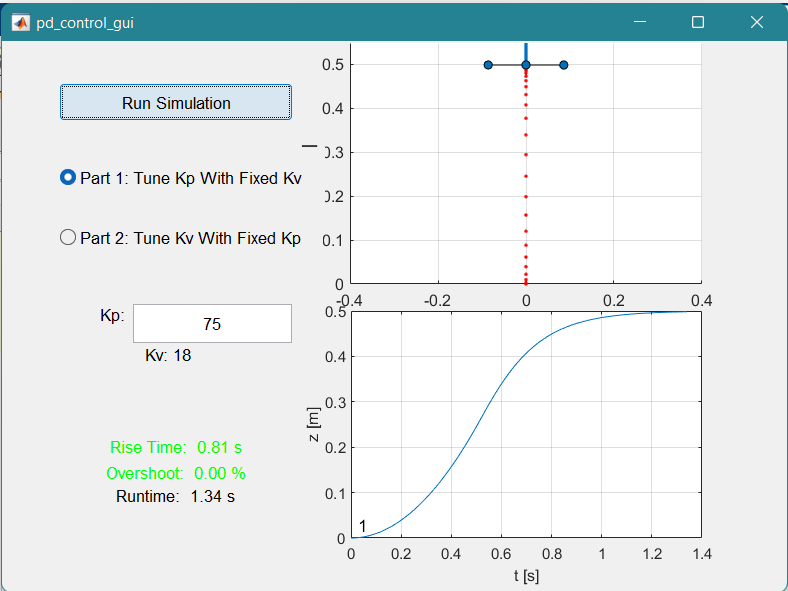

Question: Given the derivative gain $K_p$ = 100, find the proportional gain $K_v
$ value such that the rise time is less than 1s and overshoot is less than 5%.

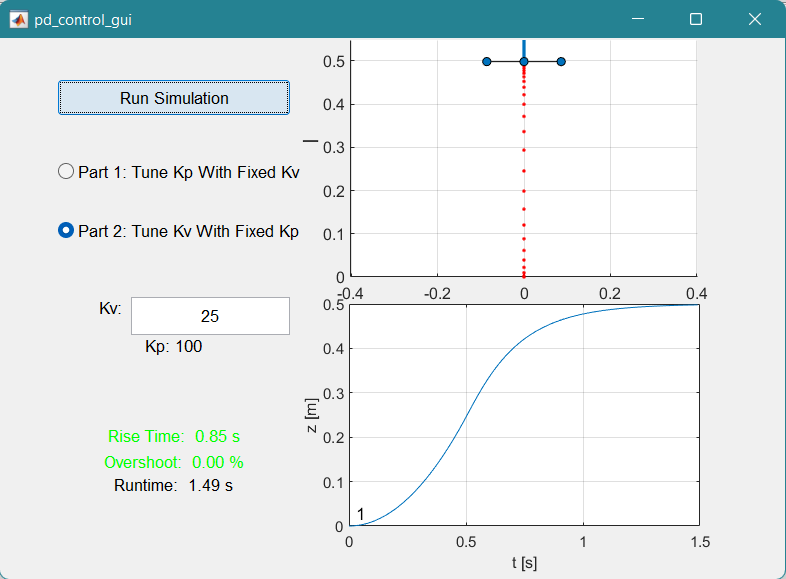

Answer: Note that this question can have multiple answers,  a key point to note that here we need to tune a PID in such a way that the requirements are satisfied, i.e rise time < 1 s and overshoot < 5%. 

Having learned about PID, let us now move towards implementing it for the 1-D quadcopter control. An important step towards the following is to learn to do appropriate PID tuning and understand the physical impacts of any variations in each of the PID gains.

[Design Consideration 1](https://www.youtube.com/watch?v=wGmCIyFj2gE)

[Example](https://drive.google.com/drive/folders/1LB2HPvt9FDq29sNMuF33YIWQXjblf8Cg?usp=sharing)

Download the simulation GUI attached above in the google drive and unzip its content to the directory you wish to complete the exercise. Open MATLAB in that directory and type "*runsim*" in MATLAB Command Window to start the GUI.

Question: Given the maximum thrust of 11.77 N (1.2 Kgf) , what is the maximum mass (kg) such that the rise time is less than 1s? 

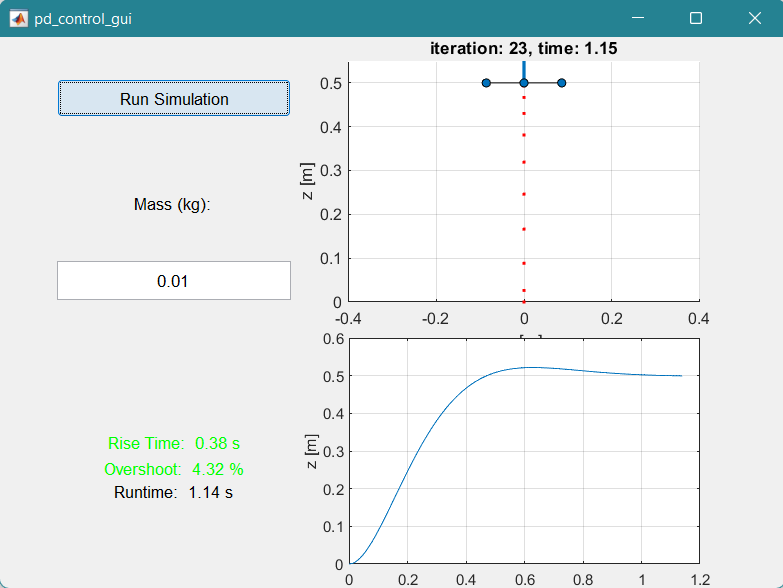

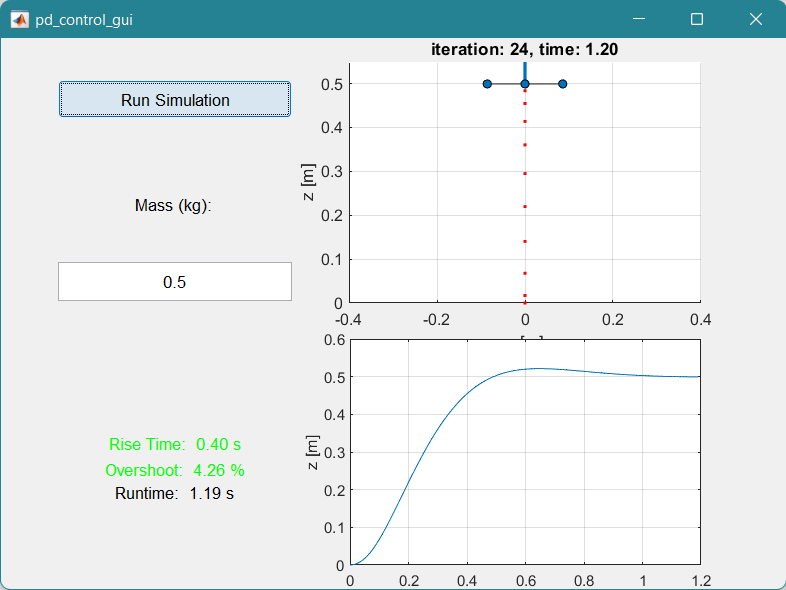

increase the mass a little by little until your rise time is just less than 1 i.e 0.99 s. The mass obtained will be the maximum mass that can rise in less than 1 s. 

lower graph shows how the z-coordinate (height) of the quad rotor changes with time. where as the above graph shows your quadrotor in action.

Ans: 1.090 kg

Now finally a bit of taste on actually designing a controller here is an example code which will be useful for you even in the upcoming assignment: [link](https://drive.google.com/drive/folders/1oJ4Tma2AP_8dwKGnE-Zv7dnVBUSHpK3H?usp=sharing)

Download the entire folder and open controller.m for the purpose of this example/exercise.

This is an attempt to show you why a P controller without D term wouldn't function for our case, and the answer isn't gravity. here I have taken a drone with 0 air resistance and no gravity and it is subjected to a simple P constroller and it desires to reach 1m height, I have added a P controller in the code  to **run the simulation type runsim **in command window. You are free to tinker with it, and see if you can make it converge (spoiler though it will never happen) and you are recommended to implement a PD controller by manupilating the code (It'll help you with the assignment).

So this week we have understood two important concepts, motor sizing and PD control implementation for 1-D quadcopter control. You will soon receive an assignment on the same two topics to improve your understanding.

The upcoming weeks would be diving into the 2-D and 3-D realms of quadcopter control. Till then... Happy Learning! :)